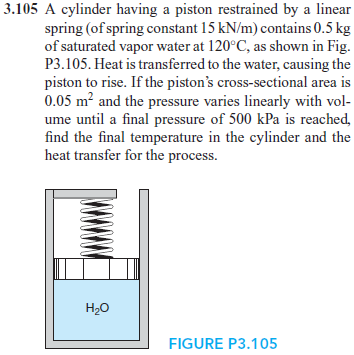

# constants

u = symunit;
k = 15*u.kN/u.m;
A = 0.05*u.m^2;

# state 1 (saturated vapor water)

% ----------------------
% steam tables
p1 = 198.5*u.kPa;
T1 = 120*u.Celsius;
v1 = 0.89186*u.m^3/u.kg;
u1 = 2529.24*u.kJ/u.kg;
% ----------------------
% volume relation
m1 = 0.5*u.kg;
V1 = m1*v1;
% ----------------------

# state 2 (superheated vapor water)

% ----------------------------------
% spring relation
syms V2;
m2 = m1;
p2 = 500*u.kPa;
V2 = solve(p2 == p1+k/A^2*(V2-V1));
V2 = simplify(V2);
% ----------------------------------
% steam tables
v2 = V2/m2;
u2 = interp1([0.98959 1.08217], [3662.17 3853.63], double(removeUnits(v2)))*u.kJ/u.kg;
T2 = interp1([0.98959 1.08217], [800 900], double(removeUnits(v2)))*u.Celsius;
T2_vpa = vpa(T2, 5) %#ok

$$T2\_vpa = 802.99\,\mathrm{{}^{\circ}C}$$

clear T2_vpa;
% ----------------------------------

# work done

W_12 = rewrite((p1+p2)*(V2-V1)/2, u.kJ);
W_12_vpa = vpa(W_12, 4) %#ok

$$W\_12\_vpa = 17.55\,\mathrm{kJ}$$

clear W_12_vpa;

# heat transfer

syms Q_12;
Q_12 = solve(m2*u2-m1*u1 == Q_12-W_12);
Q_12_vpa = vpa(Q_12, 5) %#ok

$$Q\_12\_vpa = 586.88\,\mathrm{kJ}$$

clear Q_12_vpa;